# visualizing complex B_total(t) 

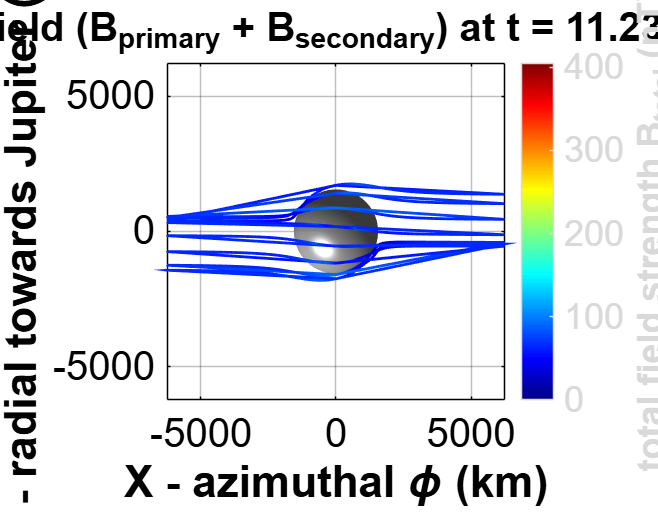

clear
% define constants
r_m = 1560; % Europa radius (km)
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / (synodic_period); % synodic freq. (rad/sec)

% elliptical primary field amplitudes from Zimmer's range (IS-system)
Bprim_x_amp = 67;  % azimuthal (orbital travel direction)
Bprim_y_amp = 225; % radial (pointing toward Jupiter)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create spatial grid
grid_limit = 4 * r_m; 
num_points = 35;       
[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points));

R = sqrt(X.^2 + Y.^2 + Z.^2);
mask = R >= r_m; 

% set up animation time array
num_frames = 60;
time_steps = linspace(0, synodic_period, num_frames);

fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 700]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% animation loop 
for t = time_steps

    r_dot_e0x = X; 
    r_dot_e0y = Y; 

    % complex secondary field: x-driven 
    coefx_c = -(A * Bprim_x_amp * r_m^3) .* exp(-1i*(omega * t - phi)) ./ (2 * R.^5);
    Bsecx_x = coefx_c .* (3 * r_dot_e0x .* X - R.^2);
    Bsecx_y = coefx_c .* (3 * r_dot_e0x .* Y);
    Bsecx_z = coefx_c .* (3 * r_dot_e0x .* Z);

    % complex secondary field: y-driven (90 deg / pi/2 shifted)
    coefy_c = -(A * Bprim_y_amp * r_m^3) .* exp(-1i*(omega*t - pi/2 - phi)) ./ (2 * R.^5);
    Bsecy_x = coefy_c .* (3 * r_dot_e0y .* X);
    Bsecy_y = coefy_c .* (3 * r_dot_e0y .* Y - R.^2);
    Bsecy_z = coefy_c .* (3 * r_dot_e0y .* Z);

    % complex primary background field
    Bprim_c_x = Bprim_x_amp * exp(-1i*omega*t);
    Bprim_c_y = Bprim_y_amp * exp(-1i*(omega*t - pi/2));

    % superimpose total field fields and take real components
    Bx = real(Bsecx_x + Bsecy_x + Bprim_c_x);
    By = real(Bsecx_y + Bsecy_y + Bprim_c_y);
    Bz = real(Bsecx_z + Bsecy_z);

    % zero interior field matrix
    Bx(~mask) = 0;
    By(~mask) = 0;
    Bz(~mask) = 0;

    % calculate total field magnitude 
    B_mag = sqrt(Bx.^2 + By.^2 + Bz.^2);


    % dynamic equator tracking from total primary field directions
    Bx_prim_now = real(Bprim_c_x);
    By_prim_now = real(Bprim_c_y);
    
    % find instantaneous alignment vector of the primary driving force
    m_real = [Bx_prim_now; By_prim_now; 0];
    m_hat = m_real / norm(m_real);

    % seed rings 
    v1 = cross(m_hat, [0; 0; 1]); 
    v1 = v1 / norm(v1);           
    v2 = [0; 0; 1];               
    
    num_seeds_per_ring = 16;
    theta = linspace(0, 2*pi, num_seeds_per_ring);
    
    % shells
    radii_layers = [1.12, 1.25] * r_m;
    
    total_seeds = length(radii_layers) * num_seeds_per_ring;
    seed_X = zeros(1, total_seeds);
    seed_Y = zeros(1, total_seeds);
    seed_Z = zeros(1, total_seeds);
    
    idx = 1;
    for r_seed = radii_layers
        for k = 1:length(theta)
            pt = r_seed * (cos(theta(k))*v1 + sin(theta(k))*v2);
            seed_X(idx) = pt(1);
            seed_Y(idx) = pt(2);
            seed_Z(idx) = pt(3);
            idx = idx + 1;
        end
    end

   
    clf;

 
    set(gcf, 'Color', 'w');
    
    % Europa
    [sx, sy, sz] = sphere(50);
    surf(sx*r_m, sy*r_m, sz*r_m, 'FaceColor', [0.75 0.75 0.75], ...
         'EdgeColor', 'none', 'FaceAlpha', 1.0);
    hold on;
    camlight('headlight'); lighting gouraud;

    verts_forward = stream3(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    verts_backward = stream3(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));
    all_verts = [verts_forward; verts_backward];

    % draw streamlines 
    for k = 1:numel(all_verts)
        v = all_verts{k};
        if isempty(v), continue; end

       
        % calculate the distance from each vertex along the line to Europa's center
        dist_from_europa = sqrt(v(:,1).^2 + v(:,2).^2 + v(:,3).^2);
        min_distance = min(dist_from_europa);
        
        % if the entire line stays further than 1.13 * r_m away, drop it
        if min_distance > 1.13 * r_m
            continue; 
        end
        

        line_colors = interp3(X, Y, Z, B_mag, v(:,1), v(:,2), v(:,3));

        patch('XData', v(:,1), 'YData', v(:,2), 'ZData', v(:,3), ...
              'FaceColor', 'none', 'EdgeColor', 'interp', ...
              'CData', line_colors, 'LineWidth', 1.4);
    end

    
    colormap(jet);
    c = colorbar;
    ylabel(c, 'total field strength B_{total} (nT)', 'FontWeight', 'bold');

    clim([0, Bprim_y_amp * 1.8]); 

    axis equal; grid on; box on;
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);
    
    ax = gca;
    set(ax, 'XColor', 'k', 'YColor', 'k', 'FontSize', 20, 'ZColor', 'k', 'Color', 'w');
    xlabel('X - azimuthal \phi (km)', 'FontWeight', 'bold');
    ylabel('Y - radial towards Jupiter (km)', 'FontWeight', 'bold');
    zlabel('Z (km)', 'FontWeight', 'bold');

    view([0 90]); 
    title(sprintf('total field (B_{primary} + B_{secondary}) at t = %.2f hours', t/3600), ...
          'Color', 'k', 'FontSize', 20 , 'FontWeight', 'bold');

    drawnow;
    pause(0.04);
end